# 5. Automated I-V Curves 

© B. Rasnow  1 Sept 25

## Objective

Use automation to measure I-V characteristic curves (of LEDs and resistors) with an Arduino microcontroller and MATLAB. In future activities, we'll rely on high speed automated measurements to study AC voltages and currents, so this activity focuses more on learning new methods than new electronic insights from the I-V curves themselves. The primary goals are to program an Arduino, and learn some new MATLAB capabilities supporting automated data acquisition and analysis. 

## Methods

[Note 21Jul24: changed R2 and R3 from 20k and 10k to 2k and 1k respectively, they maybe referenced with their prior values in the text and math below ...]

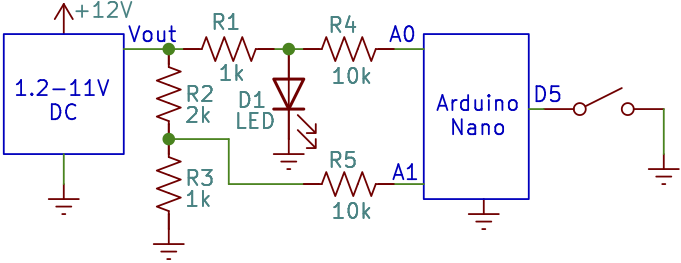

        Figure 1. Circuit for automated measuring of LED D1's I-V curve. 

The general pattern we'll repeat divides the methods into 3 principal sections. 1) Hardware interface, that includes a circuit with the device under test (DUT) that we wish to study, safely connected to the Arduino (e.g., Fig. 1). Arduino is not tolerant of voltages $Vin$ outside of $0 < Vin < 5V$. Any negative voltages or even very transient voltages > 5V will likely destroy the device. 2) Software interface, typically a program written in C in Arduino's Integrated Development Environment (IDE, [https://www.arduino.cc/en/software](https://www.arduino.cc/en/software)), that tells the Arduino which things to measure, how often, how to return the results, etc., e.g., Fig. 3. 3) Data interface, typically written in MATLAB automating data processing and visualization. It's generally important to automate all three because automated data acquisition easily generates large amounts of data that would be tedious to process manually. 

### Hardware interface

Let's explore the circuit in Fig. 1. 

- R1 and D1 are in series with the LM317 power supply and are the "test circuit". 

- D1 is often called the "device under test" or "DUT".

- The lowest voltage ~1.25V is less than the LED's (D1) $V_f$ (below its "knee") and we expect the LED to act like a very high resistance and no current flow (nor light). Raising the LM317 Vout above $V_f$ should result in approximately constant voltage ($V_f$) on D1 and a current = (Vout - $V_f$) / R1 that lights D1. 

- Arduino measures the LED voltage on pin A0, through R4. Analog inputs are "high impedance" (when $0>V>5V$ and $dV/dt$ is small), meaning they draw little current. The purpose of R4 (and R5) is protection. Imagine Vout = 10V and D1's connection to ground were disconnected. That would apply 10V to A0 through R1, which likely would destroy the Arduino. Instead of ~10V/R1 ~ 10mA cooking the Arduino, R4 reduces this current to 10V/11k < 1mA, which is less likely to damage Arduino. To be safer, before swapping D1, remember to set Vout < 5V. 

- R2 and R3 are voltage dividers that deliver Vout * R3 / (R2+R3) $\approx$ Vout / 3 to pin A1 (through protection resistor R5). The voltage divider ensures A1 < 5V always, but allows us to compute Vout = A1 * (R2+R3)/R3 $\approx$ 3 * A1. 

- I soldered R4 and R5 with short leads to a couple of white jumper wires which I treat like oscilloscope probes (I call them "Arduino probes"). 

- Pin D5 can be grounded using a jumper wire as a switch to toggle data acquisition. 

- Ensure the Arduino has a common ground with the LM317. There are two ground pins, one on either side of the Arduino. I suggest you sacrifice a 1M resistor and use its leads to connect both these pins to the blue "busses" along the top and bottom of the breadboard. You can faintly see these two wires in Figure 2. 

- Swap the DUT, D1, to test a variety of diodes, and also resistors, but WARNING: if you measure too large a resistor, R, in place of D1, you could overvoltage Arduino. R and R1 are voltage dividers, so the maximum safe R is Vout = 11.4 * R/(R+R1) = 5V $\rightarrow$ R <~700 ohms. 

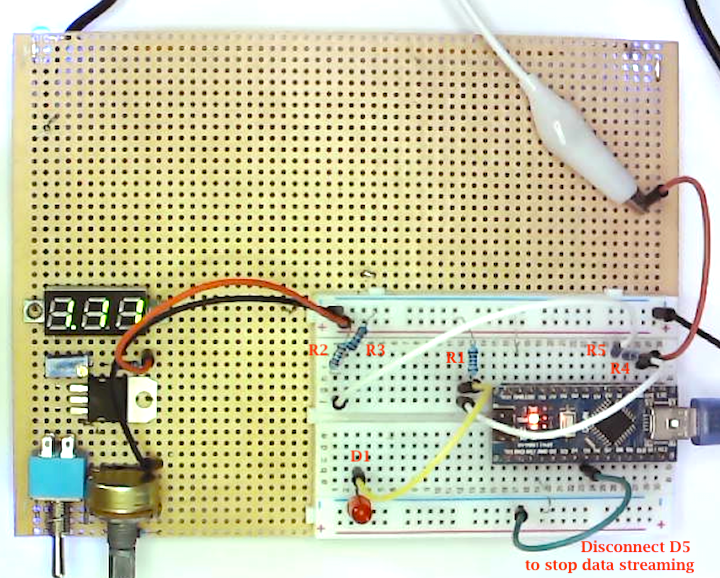

        Figure 2. Circuit of Fig. 1 implemented on the breadboard. Black and red wires on right side are clipped to the DVM to measure the Arduino's Vref pin. All other measurements are streamed through the USB cable (blue, right). Streaming stops when the green wire (bottom) is disconnected from ground

### Software interface

Before communicating with your Arduino via USB, you'll need to install a device driver for its CH340 serial chip, see the References for links to a tutorial. Next, make sure the Arduino is communicating with your computer by running from the IDE Files --> Examples --> 0.1Basics --> Blink. You may have to first select Tools --> Board --> Arduino Nano, Tools --> Port --> you'll have to find the Arduino by seeing which port appears in the menu when the Arduino is plugged in (and if none appear, then likely you didn't succeed installing the CH340 driver). Finally, Tools --> Processor --> ATmega328P --> there are 2 versions of the bootloader, if the first one doesn't load then select the other (most of our Nanos require the Old Bootloader). Getting the Blink program to blink a LED on your Arduino is a useful troubleshooting step initially and later if/when things stop working. There is no point proceeding further until all those requisite software components are working.

With confidence that you're communicating with your Arduino through the IDE, upload the following code:

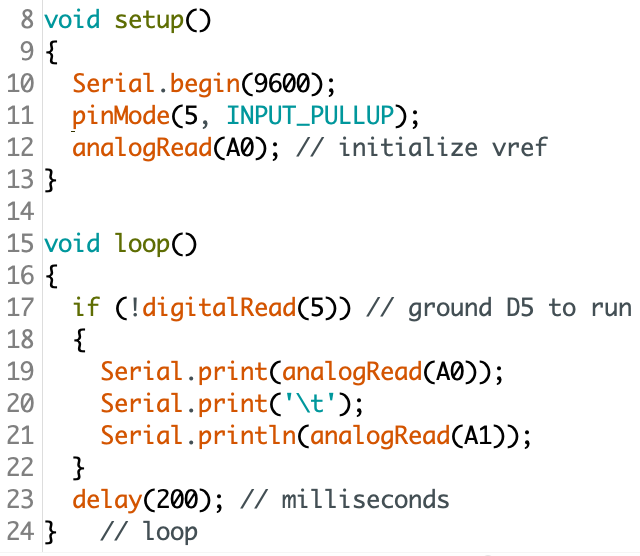

        Figure 3. Arduino software. Lines 1-7 are comments describing the application, the date, and author, that should precede any program. 

    [Note: try to copy/paste the code in Fig. 3 into your Arduino IDE. Can't do it? Because Fig. 3 is a screenshot, a photo, of the text. Frustrating isn't it, that you have to retype it all even though it's right there (and risk overlooking e.g., that the print command on line 21 is different from the previous lines -- and omitting the extra 2 letters messes everything up ...). Don't piss off your boss (or teacher) by doing this -- make sure *your *source codes and data are copy/pastable.]

How do we understand this code? I recommend as first step select in Arduino IDE --> Help menu --> Reference, and search for "Serial", "pinMode", etc. for descriptions. 

- Arduinos execute the function `setup()` once when they turn on, and then repeatedly execute `loop()`. 

- `setup` configures the Serial port to run at 9600 baud (google "baud" to learn more), and configures pin D5 as an input that's "pulled up", meaning connected via a resistor to +5V. How's that different from "INPUT"? The input value will be high unless D5 is grounded ("pulled down"). `analogRead` here initializes the data acquisition parts of the Arduino and expresses the ADC reference voltage on the vref pin. 

- `loop` has two nested blocks: if `digitalRead(5)` is false (read, "if not digitalRead(5)"), i.e. if pin D5 is grounded, lines 19-21 are executed, and line 23 is always executed, which waits 200 msec = 1/5 second. When the green wire in Fig. 2 is not grounded, Arduino just repeatedly waits. When the green wire is grounded, it reads A0 and prints the result, then `print`s a tab character (`'\t'`), and `println`'s the value of A1 (`println` prints followed by a new line character, `'\n'`). 

- The printing appears in the IDE's Serial Monitor, which you can access by clicking on the magnifying glass icon or Tools Menu --> Serial Monitor. 

Verify that 2 columns of data are printed when pin 5 is grounded, and if not then debug. What are likely bugs? Upload blink with a different delay to verify the IDE communicates with the Arduino. Then upload the code in Fig. 3 and verify the IDE didn't generate errors. Is your jumper between ground and pin D5? Did you forget a jumper (e.g., sacrificial resistor lead) between Arduino's ground pin (lower column 19) and the lower horizontal ground strip in Fig. 2? ...

### Data interface 

The Arduino prints 2 columns of measurements in the Serial Monitor in native analog-to-digital units (ADU's). Convert ADUs to volts by multiplying by the conversion factor (`vref/1023`). `vref` was measured with your DVM using a jumper wire and clip leads (right side of Fig. 2), and is the maximum voltage the Arduino can read. 1023 = 2^10 - 1, is the corresponding output in ADU. (Note, there is ambiguity whether the conversion factor should be `vref/1023` or `vref/1024`. The Arduino datasheet states 1024, but the maximum `analogRead` value is 1023.)

Column 1, A0, is the diode voltage, vd. Column 2, A1, is the power supply output scaled by the voltage divider: Vout * R3/(R2+R3). Inverting this equation gives Vout, from which we compute the current: i = (Vout-Vd)/R1. With voltage and current, the i-v curve is plotted:

#### Automating data management

Anticipating we'll want to measure many i-v curves, how should we keep track all the data (and meta-data, e.g., name of each device)? We want to avoid situations where e.g., we tested 10 devices but find only 9 voltage vectors and can't tell which one went missing. "Binding" related data together ([https://en.wikipedia.org/wiki/Data_binding](https://en.wikipedia.org/wiki/Data_binding)) reduces such risks. Right after running the above code, let's query for a device name, and combine vd and i into a data structure with that name.  E.g., if we choose to name the device "red1", then we want to execute

`>> red1.v = vd; red1.i = i;`

How can we tell MATLAB to execute that command when we don't know the device name before hand? MATLAB's `eval` command is a powerful (and a little dangerous) method for executing "self-modifying code". Construct a MATLAB command as a character string and `eval` executes the string just as if it were typed on the Command line. 

The second or 3rd line builds the command string, that's then displayed and evaluated, and finally the cell array called `varnames` is appended with the current DUT name.

Switching a variety of LEDs and resistors (with R<700$\Omega$) and repeating the measurements lets us compare characteristic curves from various devices. Be careful to avoid overwriting data, since no checking for uniqueness is performed. 

What control structure should we use to repeat for each device? Let's use MATLAB's debugger. Set a breakpoint (by clicking on the line number just below `varnames{} = dev;` add a "Section Break" below it, and click on the "Run Section" button after pasting the data for each device. 

## Results

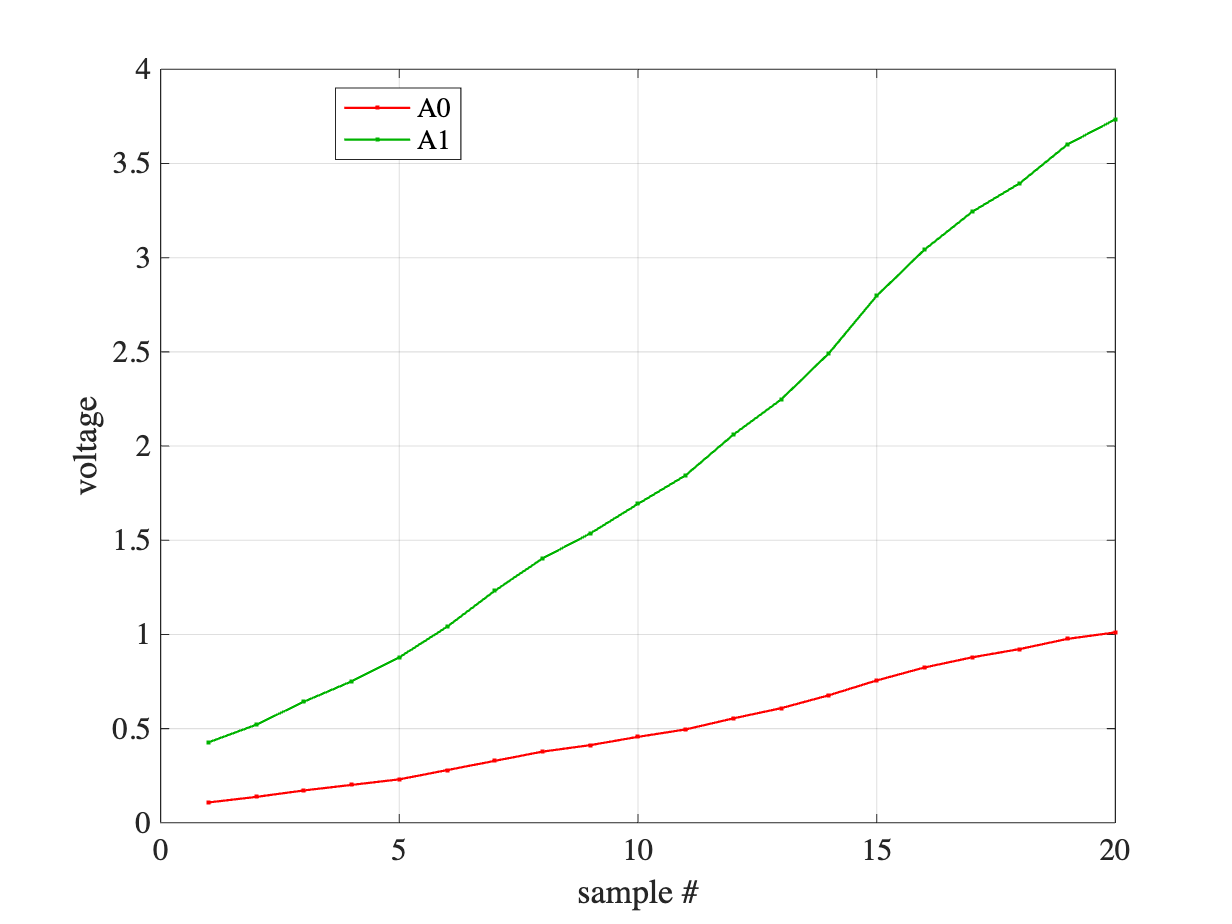

% 100 ohm resistor (the last DUT)
vref = 5.02; % volts measured on breadboard from Arduino
adu2volts = vref / 1023;
R1 = 1004; % ohms measured with DMM
R2 = 1990; % ohms
R3 = 999; % ohms
data = [... % A0 A1 pasted from Arduino IDE
22	87
28	106
35	131
41	153
47	179
57	212
67	251
77	286
84	313
93	345
101	376
113	420
124	458
138	508
154	570
168	620
179	661
188	692
199	734
206	761
] * adu2volts;
% first peek at raw data
plot(data, '.-'); grid;
xlabel('sample #'); ylabel('voltage');
legend('A0','A1','Location','best');

        Figure 4. Plot of raw data, voltages on analog input pins vs. sample #.

The raw data looks pretty wonky, because we're not turning the power supply knob perfectly smoothly. We need to compute the diode's voltages and currents from the measurements:

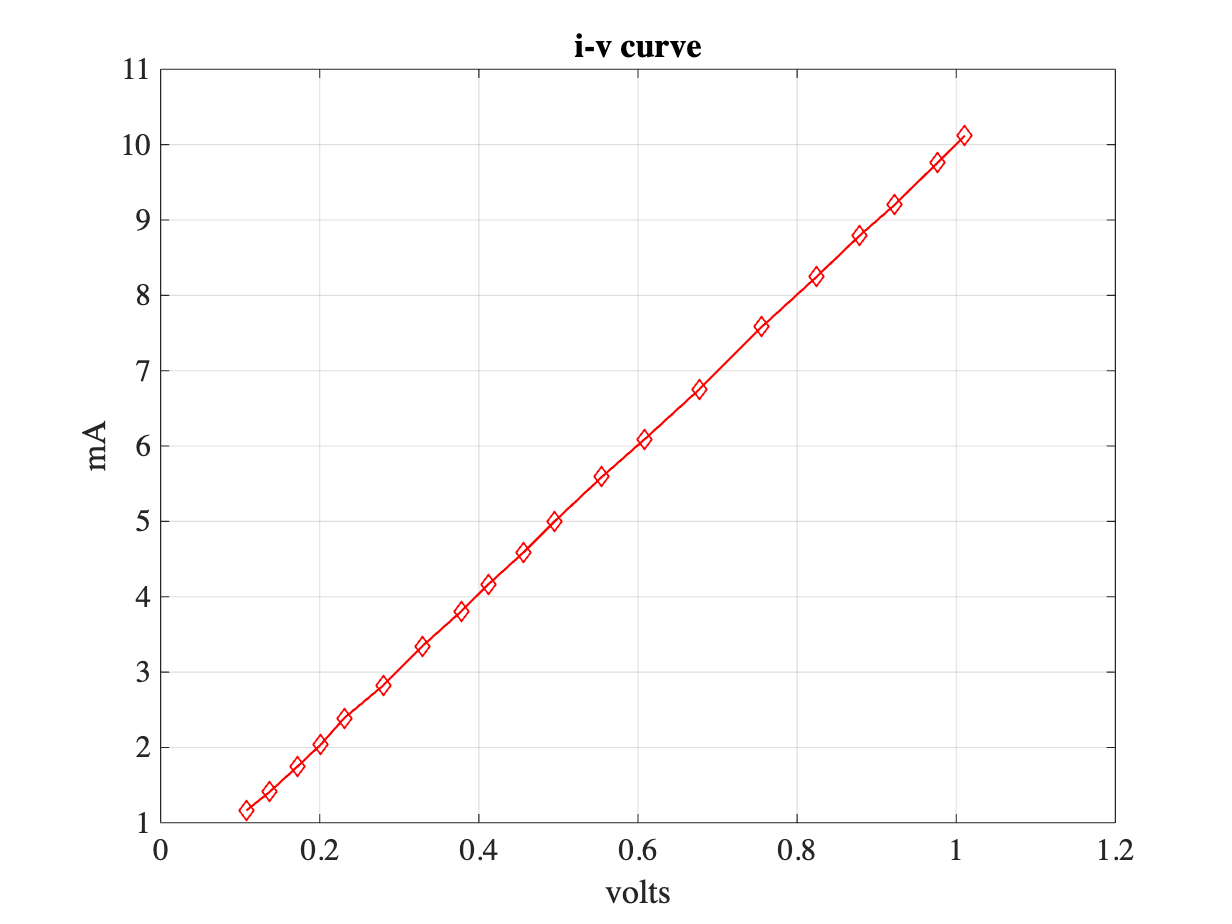

vd = data(:,1); % DUT voltage
vin = data(:,2) * (R2+R3)/R3; 
i = (vin - vd) / R1 * 1000; % mA
plot(vd, i,'d-'); grid;
xlabel('volts'); ylabel('mA'); title('i-v curve');

        Figure 5. DUT I-V curve.

Upon calculating the DUT's voltages and currents, the results appear smooth and as expected. 

To measure another device, rename the former variables in the command window, then paste new data above and rerun. This renaming and keeping track of variables can get tedious, so let's have MATLAB help us automate it:

dev = input('name this device: ', 's');
cmd = [dev '.v=vd; ' dev '.i=i;']; 
disp(cmd); 
eval(cmd);
if ~exist('varnames','var'), varnames = {}; end  % initialize a cell array for variable names
varnames{length(varnames)+1} = dev;
1; % <-- set breakpoint here by clicking on the line number at left 

Swap devices, copy/paste new data above, and stop and rerun this section to the breakpoint ...

### Combining all the data

Got enough data? After measuring several LEDs of each color (that I not-creatively named r1, r1b, g1, ...) my workspace looked like this:

whos

  Name           Size             Bytes  Class     Attributes

  R1             1x1                  8  double              
  R2             1x1                  8  double              
  R3             1x1                  8  double              
  b1             1x1                450  struct              
  b2             1x1                642  struct              
  bg             1x1                754  struct              
  cmd            1x162              324  char                
  data          32x2                512  double              
  g1             1x1                658  struct              
  g2             1x1                722  struct              
  g3             1x1                610  struct              
  i              1x1                  8  double              
  r1             1x1                626  struct              
  r100           1x1                642  struct              
  r1b            1x1                610  struct              
  r1c  

 A drawback of structures is that `whos` doesn't peek inside of them. Typing their name shows their contents: 

r1

r1 = struct with fields:
    i: [22×1 double]
    v: [22×1 double]

There are a few ways to plot all this data on one axis: 1) plot one curve at a time, using `hold`; 2) manually generate a single long plot command with all the pairs of variables; 3) ask MATLAB to make the `plot` command and `eval` it, which we'll do next. I left the semicolon off just to show the progression:

cmd = 'plot('; % the first part
for i=1:length(varnames) % add each v,i pair
    cmd = [cmd sprintf('%s.v,%s.i,', varnames{i}, varnames{i})] %; 
end

cmd = 'plot(r1.v,r1.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,b2.v,b2.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,b2.v,b2.i,r100.v,r100.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,b2.v,b2.i,r100.v,r100.i,r220.v,r220.i,'

cmd = 'plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,b2.v,b2.i,r100.v,r100.i,r220.v,r220.i,r560.v,r560.i,'

cmd = [cmd(1:end-1) ');']; % delete last comma
disp(cmd);

plot(r1.v,r1.i,r1b.v,r1b.i,r1c.v,r1c.i,y1.v,y1.i,y2.v,y2.i,g1.v,g1.i,b1.v,b1.i,g2.v,g2.i,g3.v,g3.i,bg.v,bg.i,b2.v,b2.i,r100.v,r100.i,r220.v,r220.i,r560.v,r560.i);


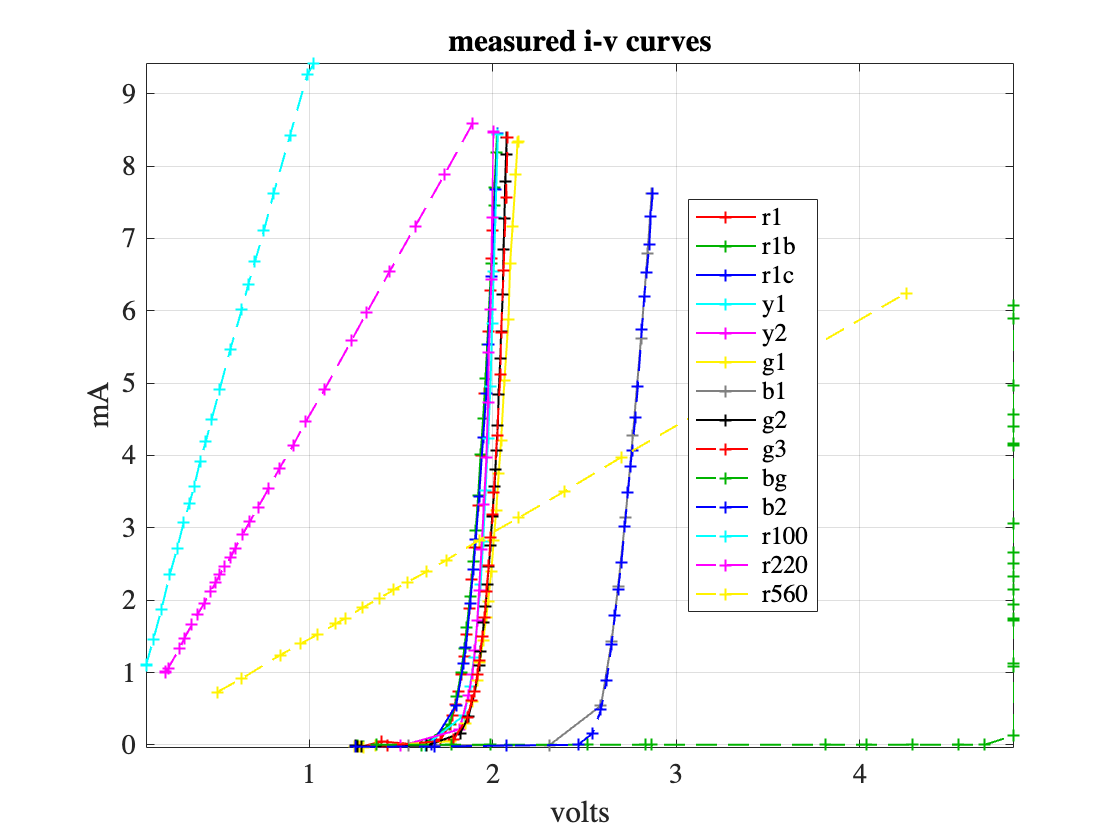

eval(cmd);
legend(varnames,'location','best'); % that was easy!!
xlabel('volts'); ylabel('mA'); title('measured i-v curves')
grid; axis tight;
dots('+') % a Rasnow function, see Appendix

        Figure 6. Combination of all the measured I-V curves -- apologies for a confusing automated coloring scheme.

What's the likelihood you could type that command without any errors? And how long would it take to find (all) the errors? 

### Saving and Loading Data

Before leaving this section, you'll probably want to save your data to a file. MATLAB's save command does that, `save <filename>` puts all the variables in your workspace into file `filename.mat` in the current directory (`>> pwd` tells you what directory that is, `cd` changes directory, ...). Data can be restored to the workspace with `load <filename>`.

## Discussion

### The Method

Using automation, we were able to measure many devices' i-v curves, recording dozens of data points for each, without major effort. Copy/paste is much faster and reliable than writing data on paper and/or typing numbers on a computer. When it came to repeating the experiment for subsequent devices, MATLAB prompted us for a device name and automated "data binding", further reducing the chances of typing errors. Finally, we automated generation of the MATLAB code to plot all the data, thus avoiding another tedious  and error prone step. If we plotted 12 curves, but the legend identified 11 or 13 curves, then finding the missing data and "frame shift" could be frustrating. Automation reduces these time-consuming errors (and worse, some errors you don't detect). Finally, repeating everything (should we need/want to) is much easier because the program is already written -- the hard part is done once. 

Having MATLAB write MATLAB code and execute it is a neat trick! Such self modifying code (SMC), [https://en.wikipedia.org/wiki/Self-modifying_code,](https://en.wikipedia.org/wiki/Self-modifying_code,) has a mixed history. It can be dangerous, it can be difficult to debug, but in this case, it saved us a lot of time and effort. Mathworks encourages you to avoid `eval`, e.g., [https://www.mathworks.com/MATLABcentral/answers/304528-tutorial-why-variables-should-not-be-named-dynamically-eval?s_tid=srchtitle_exporting%20livescript%20to%20html_2.](https://www.mathworks.com/matlabcentral/answers/304528-tutorial-why-variables-should-not-be-named-dynamically-eval?s_tid=srchtitle_exporting%20livescript%20to%20html_2.) Try the following code: 

But that's not really fair because running *any* code that you didn't create and don't understand requires trust. 

Later in the course we will eliminate (automate) the copy/paste step, using serial communication between MATLAB and Arduino. We will build a hardware+software interface enabling MATLAB to set the LM317 voltage with Arduino's `analogWrite`, R-C filters, and two transistor circuits. Then we'll be able to measure I-V curves in a few seconds without self-modifying code or `eval`. We'll learn a lot of electronics and programming by constructing those capabilities, and then by using them to explore AC circuits and their characteristics. 

### The Data

All the LEDs demonstrated diode characteristic curves that look like hockysticks: near zero current left of their "knee", followed by a steep current increase at nearly constant voltage. Repeating with LEDs of the same color result in similar curves. Vf was lowest (~1.8-2V) for red, yellow, green. Blue and white had similar Vf~2.6V. Fun fact: a white LED *is* a blue LED, with a little phosphor nearby. The phosphor absorbs some blue light and reemits it at longer wavelengths, producing the perceived white emission. I learned this because I found white LEDs cannot be quickly shut off -- the phosphor continues glowing ([phosphorescence](https://en.wikipedia.org/wiki/Phosphorescence)) for milliseconds or more, whereas other colored LEDs turn off in microseconds or less. 

The resistors have linear i-v curves, who's slope, I/V  = 1/R by Ohm's law. MATLAB has a powerful least squares fit function, >> `help polyfit` for more info. A linear fit is a polynomial or order 1, and the returned vector is [`slope y-intercept]`. Since the current is in mA and the voltage is in volts, the slope = mA/V so R(k$\Omega$) = `1/slope`: or R($\Omega$) = `1000/slope`

p = polyfit(r100.v, r100.i, 1), fprintf('r100 from slope = %.1f ohms\n', 1000/p(1))

p =     9.2077    0.1362


r100 from slope = 108.6 ohms


p = polyfit(r560.v, r560.i, 1), fprintf('r560 from slope = %.1f ohms\n', 1000/p(1))

p =     1.4717   -0.0096


r560 from slope = 679.5 ohms


The intercepts (`p(2)`) are near zero as expected. The slope of the 100$\Omega$ resistor matches within 8% of expectation, but 560$\Omega$ $\ne$ 679$\Omega$. The DMM confirmed MATLAB was correct, and the color code was further confirmation that the resistor was 680$\Omega$ and mislabeled in my kit. 

### Are diode currents exponential?

A diode's I-V curve is clearly nonlinear, but is it exponential? Three ways to answer this question are to query theory, query the data, or just guess and assume. Since we have the data, let's plot Fig. 5 on a semilogarithmic axis. If $i = ke^{\lambda (V-V_f)} $ ([https://en.wikipedia.org/wiki/Shockley_diode_equation](https://en.wikipedia.org/wiki/Shockley_diode_equation)) [4], then $log(i) = (log(k) -\lambda V_f) + \lambda V $ should be a straight line with slope $\lambda$. Recall that just below Fig. 5, we renamed our variables and overwrote the data, so you might have to change the variable names in the code first. I know of 4 ways to do a log plot. 1) `semilogy(r1.vd, r1.i,'-d')`. 2) Change the current figure axis with `set(gca, 'yscale','log')`. `gca` is a command that stands for "get current axis", returning a "handle" to the graphics object who's fields can be manipulated by `set`. `get(gca)` lists all the fields and values associated with the axis -- offering many ways to interact and modify graphs. 3) `propedit` invokes a graphical interface to the graphics object. 4) There are GUI tools in toolbars (that I'm not familiar with). But here's a 5th way: the variable `cmd = plot(....)` with all the pairs of variables. Change the first 4 characters should do the trick: 

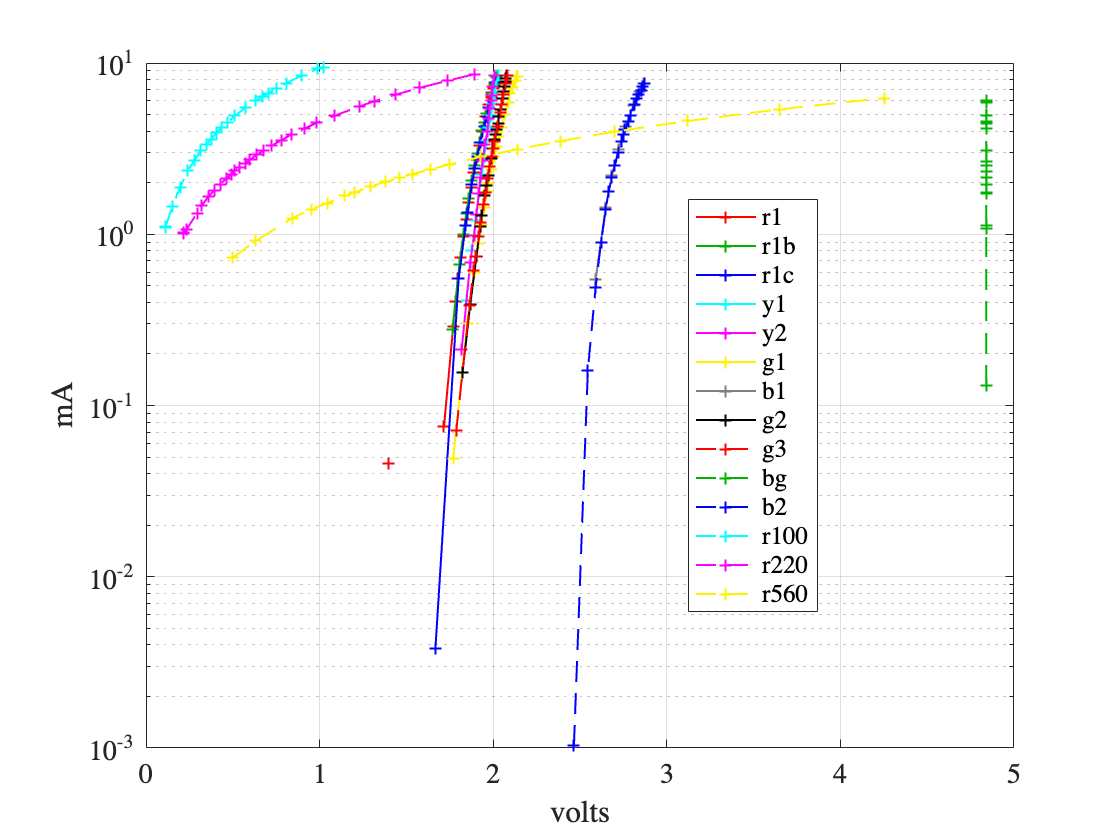

figure; 
cmd2 = ['semilogy' cmd(5:end)];
eval(cmd2); 
dots('+'); xlabel('volts'); ylabel('mA'); legend(varnames,'Location','best'); grid

        Figure 7. Fig. 6 on a semilog scale. 

Zero current isn't shown on a log plot (it's at minus infinity), and the lowest datum ~ $1x10^{-3} mA = 1\mu A$corresponds to $1\mu A * 1k \Omega * 1023ADU/4.8V$ ~ 0.2ADU, is close to (or below) the "noise floor". The diode curves are *approximately* linear on the semilog plot for currents <~1mA, consistent with *approximately* exponential behavior (at least over this range). Fig. 7 gives us more confidence (and competence) stating "the I-V curve is approximately exponential ..." than does Fig. 6. 

### The Mistake

Lots of subtleties can occur in electronic systems. I made a mistake of inserting an LED backwards, resulting in the green curve on the right of Figs. 6 and 7, reproduced in Fig. 8A that doesn't show what you may think it does. A backwards or "reverse biased" diode doesn't conduct current, and acts like a (nearly) infinite resistance. So why does the curve take off to >6mA at ~ vref ~ 5V? That is too low a voltage for the LED to [Zener breakdown](https://en.wikipedia.org/wiki/Zener_effect). The answer has *nothing* to do with the DUT, the backward LED, and in fact the current is *actually *~0.6mA!! Drawing equivalent circuits Fig. 8B) helped me figure it out.

A. 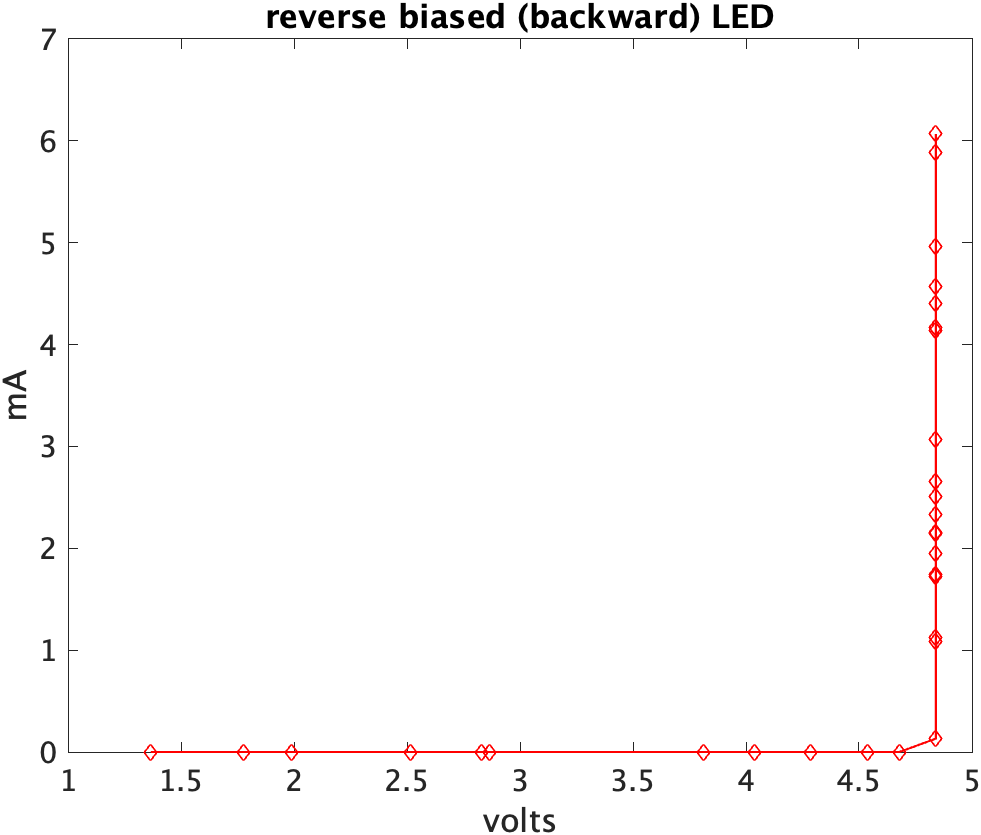

B.        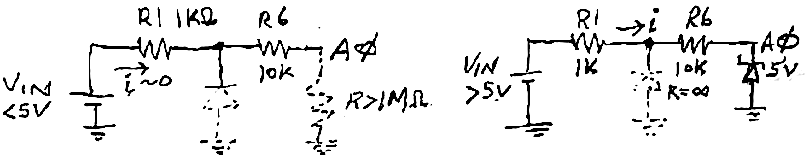

        Figure 8. A. Measured i-v curve of reverse biased LED. B. Equivalent circuit when Vin < 5V (left) and Vin > 5V (right).

As long as Vin < Vref, the current is zero because the two paths to ground in the circuit (through the backwards LED and the Arduino) are extremely high resistances (Fig. 8B left). No current means i * R1 = 0, and A0 = Vin as measured. However, when Vin > ~Vref, the Arduino's internal impedance drops. I drew a Zener diode to represent this internal impedance, but it could also be a FET or other "active", i.e., dynamic device that switched to a low impedance state. Now a current does flow through R1 (and R6): i = (Vin - 5V) / (R1+R6) < 6.4V/11k$\Omega$ ~ 0.6mA while A0 stays at 5V. So why did we "measure" i < 6mA in Fig. 6? Because we *computed* the current ignoring R6 -- assuming the current was flowing through R1 and the DUT. We computed i = (Vin - 5V)/R1, which is the right equation *if  *the LED was conducting and A0 was high impedance, but the situation with backward LED and Vin > 5V is the opposite. The voltage difference is across both R1+R6, but we divided by just R1. Note that had R6 not been there, then ~7mA would have flowed into A0, with 5V*7mA = 35mW of power delivered to a microscopic zener diode (or transistor) integrated inside the microcontroller IC, likely resulting in fatal overheating. R6 reduced that power by an order of magnitude, and the Arduino survived. 

So in summary, this mistake teaches valuable lessons, and without destroying any part. 

- If you see strange behavior from a DUT, it maybe artifact of the measuring system.

- Whereas it's much easier to "measure" current by measuring voltages over resistors, be constantly vigilant that the voltage difference measured is divided by the corresponding resistance between the voltage probes.

- Good electronic designs should be robust to errors (like placing a DUT backwards). R5 and R6 add a little complexity, they have no effect under normal operation (when Zin >> R6), but saved the Arduino from destruction during the error condition.

- Drawing schematics isn't just for designing or sharing. Drawing circuits can help us visualize and understand complex systems and their behaviors.

- Zener diodes are sometimes used to "clamp" inputs below dangerous thresholds, but those diodes have to be protected from overheating too.

- ... 

## Conclusions

As part of designing an LED night light, we measured an i-v curve of an LED, using a variable 10k resistor in series with a 12V wall wart to vary the current, and we tediously moved voltmeter probes back and forth to measure `Vd` and `Vr` across a fixed minimum resistance. Automation got us much more and better data much faster, but at a cost of complexity. Connecting to the Arduino on the solderless breadboard is easy, but we had to use a voltage divider to ensure the Arduino didn't see the full 11V of the power supply. Furthermore, we used 10k resistors in series with the analog inputs to limit input current just in case an unexpected error resulted in a higher voltage (as can happen if the DUT is an open circuit or a backwards LED). 

The Arduino software interface, even when programmed in a low-level language like C, only consisted of a few lines. Some of the code collected and sent the data to the Serial Monitor. Other lines reduced the amount of data we'd have to deal with: `delay(200)` slowed the Arduino to ~5 measurement pairs per second, and initializing and checking D5 let us implement a "data switch" with a jumper wire so the Serial Monitor doesn't constantly scroll. Keeping the Arduino software short and simple helps with the comparatively inefficient C software development environment relying on edit-compile-debug-upload cycles. Contrast to MATLAB's interpreted environment, where the command line offers instant execution and trial-and-error feedback. Programming productivity in MATLAB can be orders of magnitude greater than C, and Python is in between. Formally, C is considered a "third-generation programming language" (machine code and assembly language are the prior two) [7], whereas MATLAB is a 4-5th generation language [8].

How much data did we collect today? Ask MATLAB, maybe you can find an easier way than this: 

n = 0; 
for i=1:length(varnames)
    cmd = sprintf('n = n + length(%s.v);',varnames{i})
    eval(cmd);
end

cmd = 'n = n + length(r1.v);'

cmd = 'n = n + length(r1b.v);'

cmd = 'n = n + length(r1c.v);'

cmd = 'n = n + length(y1.v);'

cmd = 'n = n + length(y2.v);'

cmd = 'n = n + length(g1.v);'

cmd = 'n = n + length(b1.v);'

cmd = 'n = n + length(g2.v);'

cmd = 'n = n + length(g3.v);'

cmd = 'n = n + length(bg.v);'

cmd = 'n = n + length(b2.v);'

cmd = 'n = n + length(r100.v);'

cmd = 'n = n + length(r220.v);'

cmd = 'n = n + length(r560.v);'

fprintf('We collected %d data points.\n', 2*n)

We collected 604 data points.


**Assessment: **Explain why is `2*n` printed above instead of `n`? 

Key point is that data collection without automation is often a limiting factor in experiments. Doubling the data would require nearly double the effort. Automation changed that bottleneck -- doubling the data would have just meant turning the LM317 pot slower and increased the effort incrementally. Instead of focusing on data collection mechanics, you can focus your intellectual effort on a higher level -- like understanding what the data means, what does it tell you about these DUTs?

The visual (graphical) nature of characteristic curves is something engineers learn to use in designing circuits and systems. When we seek to achieve a particular "transfer function" or relationship between output and input, we can think visually of what components or systems that we know have related characteristics. Then the design becomes how to combine those sub-systems together in such ways that they produce the desired output. It's a way of of simplifying what can otherwise be very abstract and complicated. 

Look closely at the format of this report. This is a story. The Objective states the goal. The Methods are how we achieved the goal. Results are what happened when we followed the Methods. Discussion explores what the Results mean to us. We try to explain anomalies or any surprises. And here as we Conclude, we're meta-analyzing, taking another step away from the details to look at the big picture. 

What else did you learn? 

## Deeper Questions

- Assume Vref = 4.5V. What's the minimum voltage you can measure with your Arduino (in the absence of noise -- you might be surprised that noise *might* help you measure smaller voltages -- a phenomena called "[stochastic resonance](https://en.wikipedia.org/wiki/Stochastic_resonance)")?

- Now assume you're measuring current as a voltage across a 1k$\Omega$ series resistor. What is the smallest current you can measure with an Arduino (in the absense of noise -- you might be surprised that noise *might* help you measure smaller currents via "[stochastic resonance](https://en.wikipedia.org/wiki/Stochastic_resonance)").

- Switching the 1k$\Omega$ series resistor to a 100k$\Omega$ would measure 1/100 the current at the same voltage, $V = iR$. Why might this strategy to increase sensitivity not work?

- Diodes and resistors can do logic operations. Consider the two circuits below, with the assumption that inputs (X, Y) and outputs are classified by 0 < voltage < 2V = logic "0" and 2.5V < voltage < 5V = logic "1". Complete the output or "truth tables" for these circuits. Which of these is an OR gate? Which is an AND gate?

            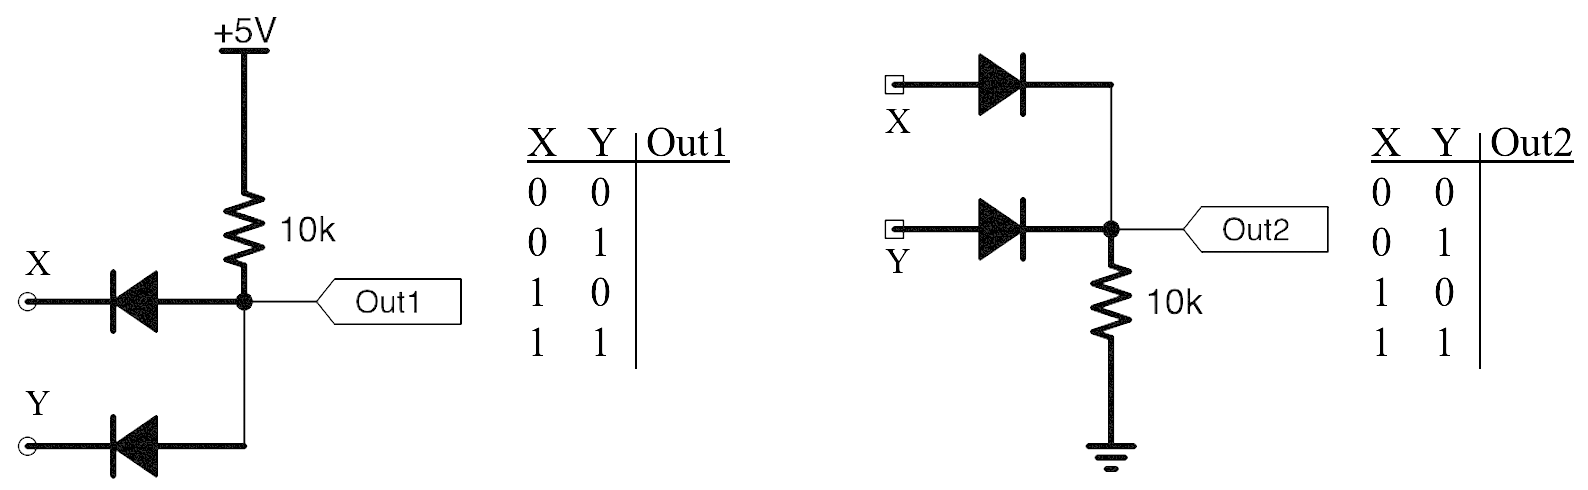

            Figure 9. Diode-resistor logic circuits.

        In 2 weeks we'll see how a transistor and a resistor (or 2 transistors) can do logic NOT or "invert" its input, which in principle are all the circuits necessary to build a general purpose computer ([Turing Machine](https://en.wikipedia.org/wiki/Turing_machine)). 

## Appendix: dots.m

This function adds data markers to all the lines on the current plot and brings the figure to the front. Common markers are  '+' | 'o' | '*' | '.' | 'x' | 'square' | 'diamond' 'none'.  `>> doc marker `gives more details. 

function dots(marker)
% function dots(marker)		12 oct 98 BR
% dots -- set the marker on the current axis to dots (default)

if nargin == 0 % set default
    marker = '.';
end
h = get(gca, 'Children');
for i=1:length(h)
    if isequal(get(h(i),'Type'),'line')
        set(h(i),'Marker', marker);
    end
end
figure(gcf);
end

## References

- Download the Arduino IDE at [https://www.arduino.cc/en/software.](https://www.arduino.cc/en/software.)

- Download the Arduino Serial driver at: [https://learn.sparkfun.com/tutorials/how-to-install-ch340-drivers/all](https://learn.sparkfun.com/tutorials/how-to-install-ch340-drivers/all) 

- We applied self-modifying code in this script, which has a dubious history. E.g., [https://en.wikipedia.org/wiki/Self-modifying_code,](https://en.wikipedia.org/wiki/Self-modifying_code,) [https://www.mathworks.com/MATLABcentral/answers/304528-tutorial-why-variables-should-not-be-named-dynamically-eval?s_tid=srchtitle_exporting%20livescript%20to%20html_2.](https://www.mathworks.com/matlabcentral/answers/304528-tutorial-why-variables-should-not-be-named-dynamically-eval?s_tid=srchtitle_exporting%20livescript%20to%20html_2.)

- A theoretical equation of a diode's I-V relation is named after a co-inventor of the transistor (and notorious racist): [https://en.wikipedia.org/wiki/Shockley_diode_equation](https://en.wikipedia.org/wiki/Shockley_diode_equation) 

- Analog input circuitry of the Arduino is described on page 212 of the microcontroller's datasheet, [https://ww1.microchip.com/downloads/en/DeviceDoc/Atmel-7810-Automotive-Microcontrollers-ATmega328P_Datasheet.pdf](https://ww1.microchip.com/downloads/en/DeviceDoc/Atmel-7810-Automotive-Microcontrollers-ATmega328P_Datasheet.pdf) and is also discussed in other websites, e.g., [https://forum.arduino.cc/t/input-impedance-of-a0-a5/64820.](https://forum.arduino.cc/t/input-impedance-of-a0-a5/64820.) 

- P. 215 of the ATmega320P datasheet also gives the conversion factor: ADC = Vin * 1024 / Vref -- other sources use 1023 in the numerator. Fun fact about this datasheet: the Table of Contents begins on p. 289, at the *end*. OK!

- [https://en.wikipedia.org/wiki/Third-generation_programming_language.](https://en.wikipedia.org/wiki/Third-generation_programming_language.)  [https://en.wikipedia.org/wiki/Fourth-generation_programming_language](https://en.wikipedia.org/wiki/Fourth-generation_programming_language) 

- [https://www.computerhope.com/history/programming.htm](https://www.computerhope.com/history/programming.htm)  